img = imread("../db/DB1/db1_03.jpg");
imshow(img)
hybrid_mask = hybrid(img);


% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)

%Find eyes and a mouth
eyes = eyemap(img_gw);
eye_mask = eyemask(eyes,face_mask);

imshow(eye_mask)
imshow(hybrid_mask)

mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)

[x,y] = mouth_index(mouth_mask);

imshow(img)
[indexX,indexY] = eye_index(eye_mask)

indexX =     53   124   154   235   266   336


indexY =    242   248   373   370   249   260


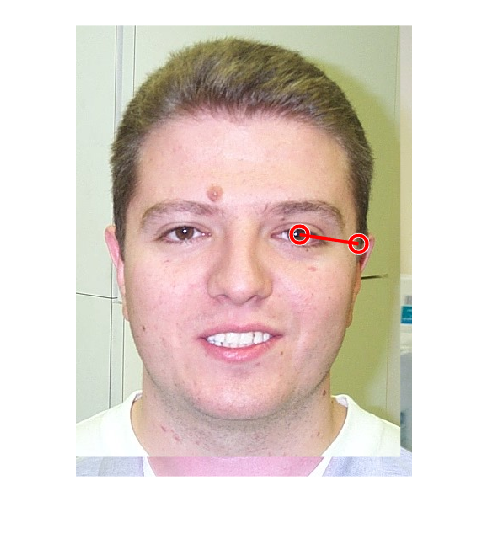

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


eye1 =    266   249


eye2 =    336   260


mouth_center = [x, y]; % replace with actual coordinates
[eye1 , eye2] = findEyePair(indexX,indexY,mouth_center)